# Creating Plots

For website

addpath('Data\')
clc, clear

%5 point moving average filter
g1_time = ParseMatlabAppFinal('G1');
g1_filt = move_avg_filt(g1_time, 5);
b1_time = ParseMatlabAppFinal('B1');
b1_filt = move_avg_filt(b1_time, 5);

g1time_4_time = g1_time.t_Accel(10:end-10);
new_g1time_4_time = g1time_4_time - g1time_4_time(1);

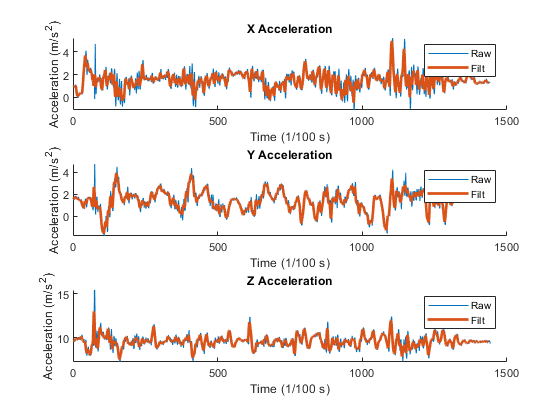

%visualize time domain for filtered vs unfiltered
clf
figure()
%sgtitle('Visualizing Time Domain')
subplot(3,1,1)
hold on
plot(g1_time.Accel(10:end-10, 1))
plot(g1_filt(:,1), 'LineWidth', 2)
title('X Acceleration')
xlabel('Time (1/100 s)')
ylabel('Acceleration (m/s^2)')
hold off
legend('Raw', 'Filt')
subplot(3,1,2)
hold on
plot(g1_time.Accel(10:end-10, 2))
plot(g1_filt(:,2), 'LineWidth', 2)
title('Y Acceleration')
xlabel('Time (1/100 s)')
ylabel('Acceleration (m/s^2)')
hold off
legend('Raw', 'Filt')
subplot(3,1,3)
hold on
plot(g1_time.Accel(10:end-10, 3))
plot(g1_filt(:,3), 'LineWidth', 2)
title('Z Acceleration')
xlabel('Time (1/100 s)')
ylabel('Acceleration (m/s^2)')
hold off
legend('Raw', 'Filt')

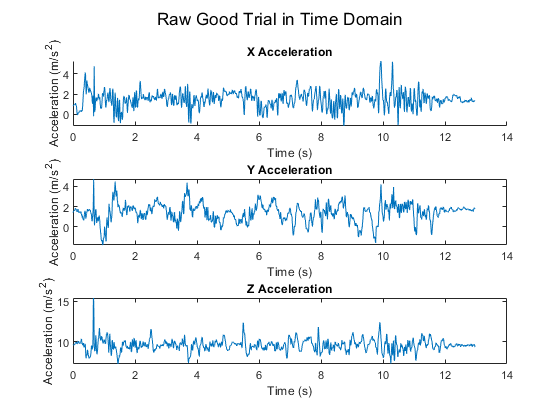

%visualize raw unfiltered data in time domain

clf
figure()
sgtitle('Raw Good Trial in Time Domain')
subplot(3,1,1)
hold on
plot(new_g1time_4_time,g1_time.Accel(10:end-10,1))
title('X Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
subplot(3,1,2)
plot(new_g1time_4_time,g1_time.Accel(10:end-10,2))
title('Y Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
subplot(3,1,3)
plot(new_g1time_4_time,g1_time.Accel(10:end-10,3))
title('Z Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

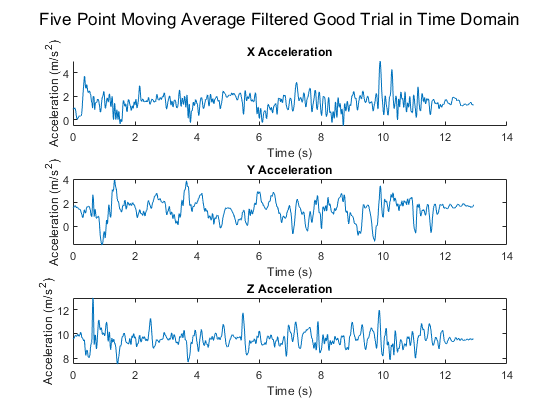

%visualize filtered data in time domain

filt_g1time_4_time = new_g1time_4_time(3:end-3,:);
newfilt_g1time_4_time = filt_g1time_4_time - filt_g1time_4_time(1);

clf
figure()
sgtitle('Five Point Moving Average Filtered Good Trial in Time Domain')
subplot(3,1,1)
hold on
plot(newfilt_g1time_4_time,g1_filt(:,1))
title('X Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
subplot(3,1,2)
plot(newfilt_g1time_4_time,g1_filt(:,2))
title('Y Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
subplot(3,1,3)
plot(newfilt_g1time_4_time,g1_filt(:,3))
title('Z Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

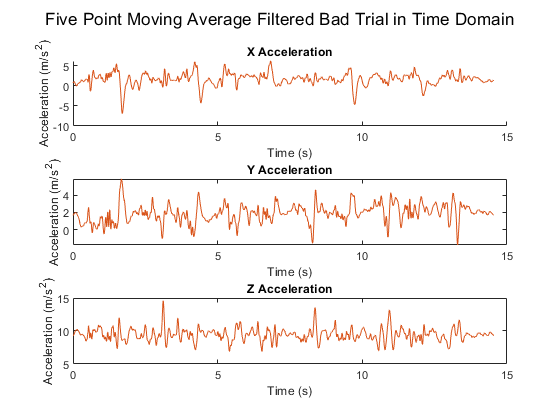

%visualize bad data in time domain

%b1time_4_time = b1_time.T_Accel;
b1time_4_time = b1_time.t_Accel(10:end-10);
new_b1time_4_time = b1time_4_time - b1time_4_time(1);
filt_b1time_4_time = new_b1time_4_time(3:end-3,:);
newfilt_b1time_4_time = filt_b1time_4_time - filt_b1time_4_time(1);

clf
figure()
sgtitle('Five Point Moving Average Filtered Bad Trial in Time Domain')
subplot(3,1,1)
hold on
plot(newfilt_b1time_4_time,b1_filt(:,1),'Color','#D95319')
title('X Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
subplot(3,1,2)
plot(newfilt_b1time_4_time,b1_filt(:,2),'Color','#D95319')
title('Y Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
subplot(3,1,3)
plot(newfilt_b1time_4_time,b1_filt(:,3),'Color','#D95319')
title('Z Acceleration')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

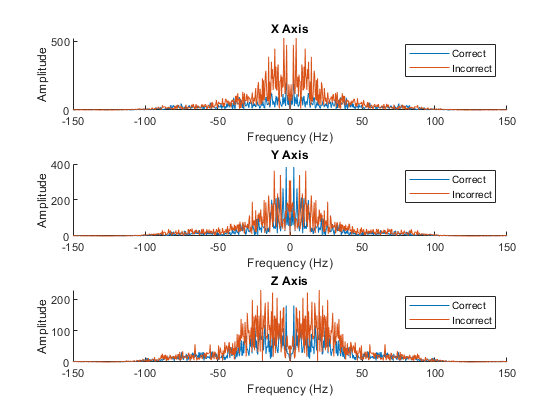

%comparison in frequency domain

g1_5 = process_data('G1');
b1_5 = process_data('B1');

clf
figure()
hold on
%sgtitle('Frequency Domain Good Vs. Bad Not Perpindicular to Body')
subplot(3,1,1)
hold on
plot(g1_5(:,1), abs(g1_5(:,2)))
plot(b1_5(:,1), abs(b1_5(:,2)))
xlim([-150 150])
legend('Correct', 'Incorrect')
title('X Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off
subplot(3,1,2)
hold on
plot(g1_5(:,1), abs(g1_5(:,3)))
plot(b1_5(:,1), abs(b1_5(:,3)))
xlim([-150 150])
legend('Correct', 'Incorrect')
title('Y Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off
subplot(3,1,3)
hold on
plot(g1_5(:,1), abs(g1_5(:,4)))
plot(b1_5(:,1), abs(b1_5(:,4)))
xlim([-150 150])
legend('Correct', 'Incorrect')
title('Z Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off

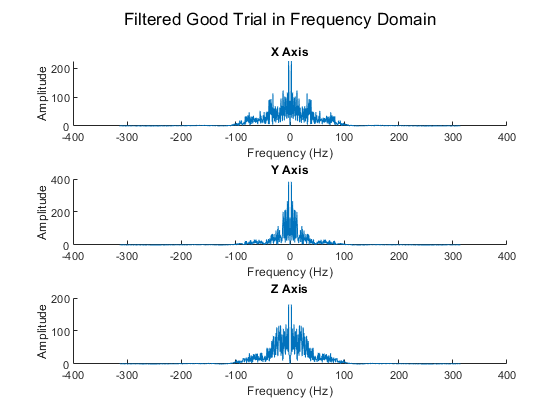

% just good in frequency domain
clf
figure()
hold on
sgtitle('Filtered Good Trial in Frequency Domain')
subplot(3,1,1)
hold on
plot(g1_5(:,1), abs(g1_5(:,2)))
%plot(b1_5(:,1), abs(b1_5(:,2)))
%legend('Good')%, 'Bad')
title('X Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off
subplot(3,1,2)
hold on
plot(g1_5(:,1), abs(g1_5(:,3)))
%plot(b1_5(:,1), abs(b1_5(:,3)))
%legend('Good')%, 'Bad')
title('Y Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off
subplot(3,1,3)
hold on
plot(g1_5(:,1), abs(g1_5(:,4)))
%plot(b1_5(:,1), abs(b1_5(:,4)))
%legend('Good')%, 'Bad')
title('Z Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off

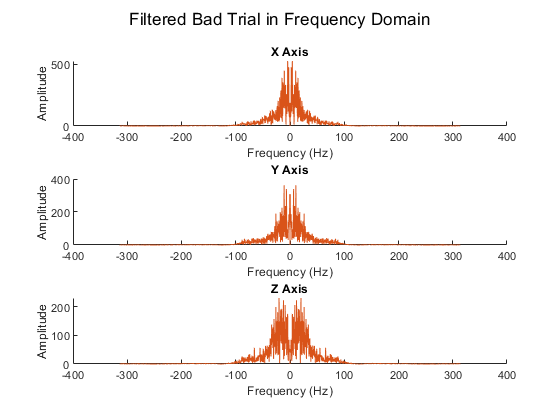

%just bad frequency domain

clf
figure()
hold on
sgtitle('Filtered Bad Trial in Frequency Domain')
subplot(3,1,1)
hold on
%plot(g1_5(:,1), abs(g1_5(:,2)))
plot(b1_5(:,1), abs(b1_5(:,2)),'Color','#D95319')
%legend('Bad')
title('X Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off
subplot(3,1,2)
hold on
%plot(g1_5(:,1), abs(g1_5(:,3)))
plot(b1_5(:,1), abs(b1_5(:,3)),'Color','#D95319')
%legend('Bad')
title('Y Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off
subplot(3,1,3)
hold on
%plot(g1_5(:,1), abs(g1_5(:,4)))
plot(b1_5(:,1), abs(b1_5(:,4)),'Color','#D95319')
%legend('Bad')
title('Z Axis')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off

%showing effect of low pass filter

g1_freq = fft_from_time(g1_time.Accel,100)

g1_freq = 	1.0e+04 *

  -0.0314 + 0.0000i  -0.0001 + 0.0001i  -0.0002 - 0.0000i  -0.0000 - 0.0001i
  -0.0314 + 0.0000i  -0.0001 - 0.0001i  -0.0001 - 0.0002i   0.0002 - 0.0001i
  -0.0313 + 0.0000i  -0.0000 + 0.0001i  -0.0001 - 0.0001i   0.0002 - 0.0002i
  -0.0313 + 0.0000i  -0.0001 + 0.0001i  -0.0000 + 0.0001i   0.0003 - 0.0002i
  -0.0312 + 0.0000i  -0.0001 + 0.0002i  -0.0002 + 0.0004i  -0.0001 - 0.0001i
  -0.0312 + 0.0000i  -0.0001 + 0.0000i  -0.0001 + 0.0001i   0.0000 - 0.0001i
  -0.0311 + 0.0000i  -0.0001 - 0.0000i  -0.0001 - 0.0001i  -0.0000 - 0.0003i
  -0.0311 + 0.0000i   0.0001 + 0.0002i   0.0001 + 0.0004i  -0.0000 + 0.0001i
  -0.0311 + 0.0000i   0.0000 + 0.0002i  -0.0000 + 0.0004i  -0.0004 - 0.0003i
  -0.0310 + 0.0000i  -0.0001 + 0.0000i   0.0002 + 0.0002i  -0.0005 - 0.0000i


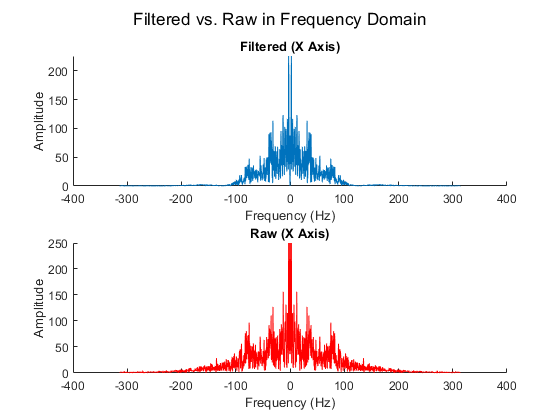


clf
figure()
hold on
sgtitle('Filtered vs. Raw in Frequency Domain')
subplot(2,1,1)
hold on
plot(g1_5(:,1), abs(g1_5(:,2)))
title('Filtered (X Axis)')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
hold off
subplot(2,1,2)
hold on
plot(g1_freq(:,1), abs(g1_freq(:,2)),'r')
title('Raw (X Axis)')
xlabel('Frequency (Hz)')
ylabel('Amplitude')
axis([-400 400 0 250])  %length(g1_freq(:,1))
hold off

%legend('Filtered', 'Raw')

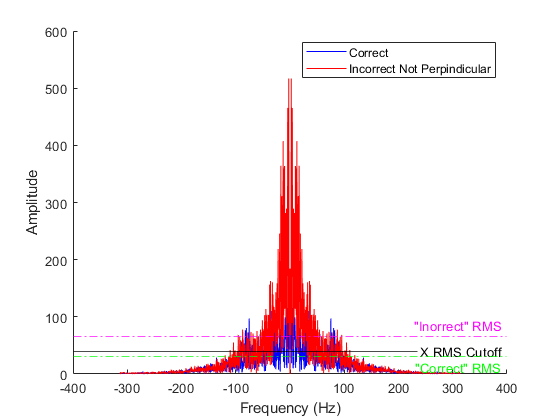

%show difference between good and not perpindicular in freq domain (with
%RMS cut-off shown)
%** IS THIS GRAPH TOO BUSY?
good1 = fft_from_time(g1_time.Accel, 100);
bad1 = fft_from_time(b1_time.Accel, 100);
good1 = remove_0(good1);
bad1 = remove_0(bad1);
good_rms = rms(good1(:,2));
bad_rms = rms(bad1(:,2));
clf
figure();
hold on
plot(good1(:,1), abs(good1(:,2)), 'b');
plot(bad1(:,1), abs(bad1(:,2)), 'r');
yline(40, 'k', 'X RMS Cutoff', 'labelVerticalAlignment', 'middle');
yline(good_rms, '-.g', '"Correct" RMS', 'labelVerticalAlignment', 'bottom');
yline(bad_rms, '-.m', '"Inorrect" RMS', 'labelVerticalAlignment', 'top');
xlabel('Frequency (Hz)')
ylabel('Amplitude')
%title('Good vs. Bad Not Perpindicular In X Axis')
legend('Correct', 'Incorrect Not Perpindicular')

function fft_data = process_data(file_name)
% process_data gets data ready to be fed into algorithm
% file_name: name of data file. Note: must be in Data folder
% returns data in frequency domain (with lowpass filter and 0Hz removed)

data_time = ParseMatlabAppFinal(file_name); %parse data file from Matlab App
data_filt = move_avg_filt(data_time, 5); %perform moving average filter (low-pass filter) on time data
fft_data = fft_from_time(data_filt, 100); %take fft of filtered data
fft_data = remove_0(fft_data); %remove 0Hz frequency
end

function freq_data = remove_0(freq_data)
% remove_0 removes the 0Hz frequency from all axes
% input freq_data: frequency data matrix (N x 3)

    %for each axis: find max frequency (will be 0Hz) and make amplitude 0
    for i=2:4
        [~, Index] = max(freq_data(:,i));
        freq_data(Index, i) = 0;
    end
end